# Adaptive Model Predictive Control for Leukemia Treatment

## Initialization

clear all;
clc; 
close all; 

% Initialization (from Jost et al. - population average)
bsa = 1.71; % should be from patient data
p_actual = [2.06; 0.146; 0.103; 0.866]; % true value of theta 6,7,8,9
p_guess = [0.75; 1.96; 1.35; 1.75];

Note: changing theta 6 and 9 seem to have the largest impact on outcome

- theta 6's initial guess can't be too far away from the actual value

- theta 9 is very sensitive, I noticed that when it was initialized to something lower than the actual value, it had a really hard time predicting the true value, but it could handle initial values much greater than the true value.

- sometimes it's not the problem that they don't uncover the correct value, but they impact the other parameters (e.g. increasing theta 9's value too high causes theta 8 to converge to the wrong value)

Note: algorithm doesn't handle input or output noise very well

- adding input noise to the model e.g. replacing jost_discrete with jost_noisy for all functions makes it diverge from the nominal trajectory a lot

- adding output noise (to y_k_obs in calc_params function) is a bit better but still had a hard time converging to the optimal solution 

- adding noise to the nominal trajectory didn't make a big difference in performance, still tracked well! (tried with var_w = 0.01 and 0.025 with no problems, anything > 0.05 starts to look very different to the nominal trajectory)

- overall, the more noise, the longer it takes to converge

Note: points of weakness

- adding lower bound to calc_params fmincon (on line 123) causes the algorithm to break for some reason (I think it's because fmincon needs to go negative for it to arrive at the solution but not quite sure) 

- sometimes adding too much noise causes fmincon to explode (the error goes to infinity)

theta = [ ...
    31.2; ...
    12.72; ...
    0.019; ...
    9.9216; ...
    0.219*(bsa^1.16); ...
    p_actual(1); ...
    p_actual(2); ...
    p_actual(3); ...
    p_actual(4); ...
    2.3765; ...
];

% initial values (from Jost et al.)
x0 = [0;...
    0;...
    0;...
    theta(6)*theta(10)/theta(7);...
    theta(6)*theta(10)/theta(7);...
    theta(6)*theta(10)/theta(7);...
    theta(6)*theta(10)/theta(7);...
    theta(6)];

N = 17; % number of cycles
N_cycledays = 21; % for Steve we use 21 days
N_drugdays = 14; % for Steve we use 14 days

% Dimension
n = 8; % dimension of state vector x 
m = 1; % dimension of observation vector y

step_size = 0.05;
num_tpts = N_cycledays/step_size + 1;
tspan = linspace(0, N_cycledays, num_tpts);

t_oncycle = N_drugdays/step_size;
t_offcycle = (N_cycledays-N_drugdays)/step_size;
t_fullcycle = t_oncycle + t_offcycle + 1;

lower = 1; upper = 2;
var_w = 0.025;

## Nominal Trajectory

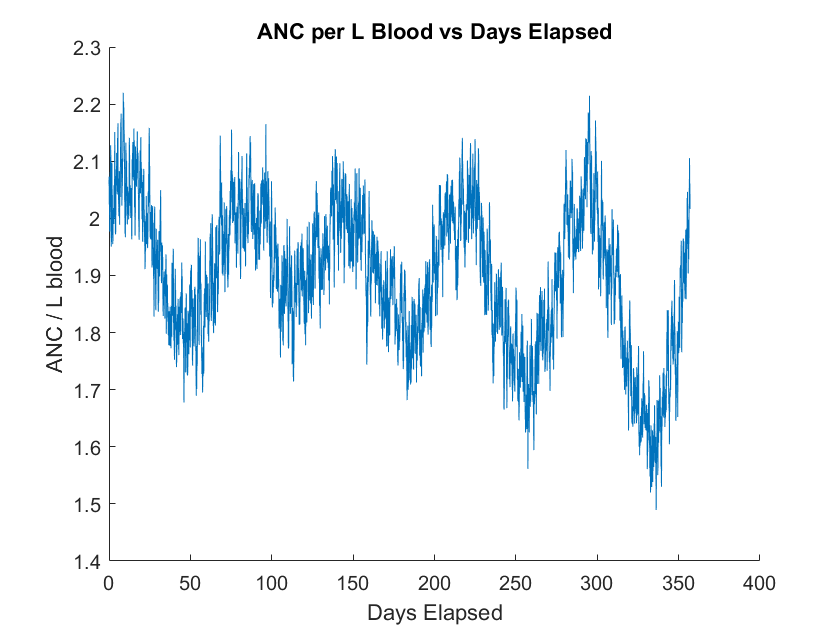

% Simulation Length
N_cyclestotal = N;
N_days=N_cycledays*N_cyclestotal;

t_s = step_size;
N_steps = N_days / t_s;
N_steps_per_day = 1 / t_s;
time = (0:t_s:N_days);

% Nominal trajectory with new time vector
x_nominal = zeros([N_steps+1 n]);
u_nominal = zeros([N_steps+1 1]);
rho = zeros([N_steps+1 m]);

u_k=50*bsa;
x_nominal(1,:) = x0;
rho(1,:) = g_nonlin(x0);

for k=1:N_days
    day_in_cycle = get_cycle_day(k, N_cycledays);
    for i=1:N_steps_per_day
        j = (N_steps_per_day*(k-1) + i);
        if day_in_cycle <= N_drugdays
            u_nominal(j,:) = u_k;
        end
        x_nominal(j+1,:) = jost_noisy(...
            (j+1)*t_s,x_nominal(j,:)',u_nominal(j,:),p_actual,N_cycledays,N_drugdays,var_w,t_s ...
        );
        rho(j+1, :) = g_nonlin(x_nominal(j+1,:));
    end
    if day_in_cycle == N_cycledays
        x_k = x_nominal(j+1,:);
        if x_k(8) < lower
            u_k = 0.8*u_k;
        elseif x_k(8) > upper
            u_k = 1.2*u_k;
        end
    end
end

figure()
hold on
xlabel('Days Elapsed')
ylabel('ANC / L blood')
title("ANC per L Blood vs Days Elapsed")
plot(time,rho)
hold off

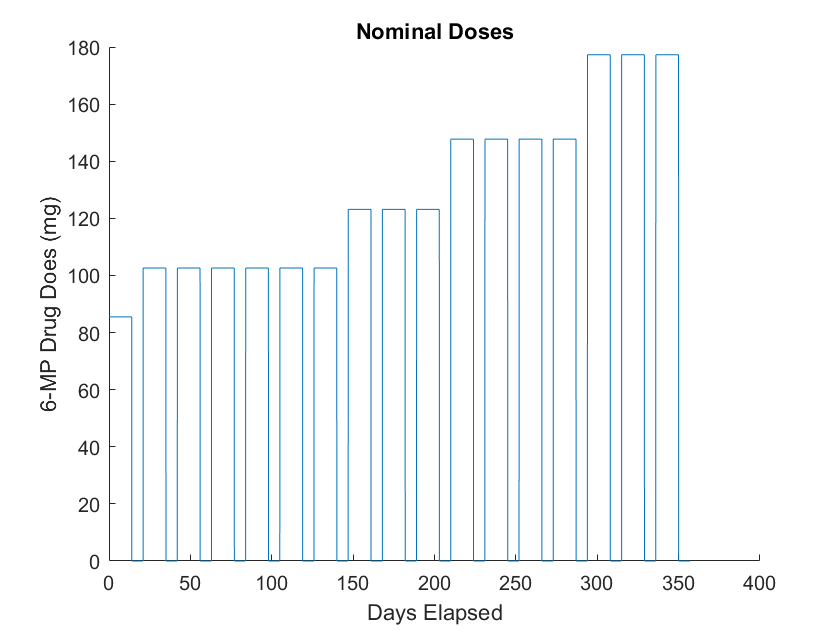


figure()
hold on
xlabel('Days Elapsed')
ylabel('6-MP Drug Does (mg)')
title("Nominal Doses")
plot(time,u_nominal)
hold off

## Adaptive Model Predictive Controller

N_cyclespred = 4; %floor(N/5);
N_dayspred=N_cycledays*N_cyclespred;

n_params = length(p_actual);
x_calc = zeros([n,1,N_steps+1]);
y_calc = zeros([m,1,N_steps+1]);
params_calc = zeros([n_params,1,N_cyclestotal+1]);
u_calc = zeros([1,N_days]);

x_calc(:,:,1) = x0;
y_calc(:,:,1) = g_nonlin(x0);
params_calc(:,:,1) = p_guess;

for k=0:N_cycledays:N_days-1
    prev_step = N_steps_per_day*k + 1;  
    cycle = floor(k/N_cycledays)+1;
    
    f = @(p)calc_params(p, p_actual, x0, u_calc, prev_step, N_cycledays, N_drugdays, t_s);
    [p_star, fval] = fmincon(f,params_calc(:,:,cycle));

    g = @(u)calc_control(...
        p_star, rho, x_calc(:,:,prev_step), k, u, 10, 0.0001, N_dayspred, N_cyclespred, N_cycledays, N_drugdays, t_s ...
    );

    init_guess_u = 50*bsa;
    [u_star, gval] = fmincon(g,repmat(init_guess_u, [N_cyclespred 1]), [], [], [], [], repmat(0.01, [N_cyclespred 1]));
    u_calc(k+1:k+N_drugdays) = u_star(1);

    params_calc(:,:,cycle+1) = p_star;
    
    for i=prev_step:prev_step + N_steps_per_day*N_cycledays - 1
        x_calc(:,:,i+1) = jost_discrete((i+1)*t_s,x_calc(:,:,i), u_star(1),p_actual,N_cycledays,N_drugdays,t_s);
        y_calc(:,:,i+1) = g_nonlin(x_calc(:,:,i+1));
    end
end


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


## Plots

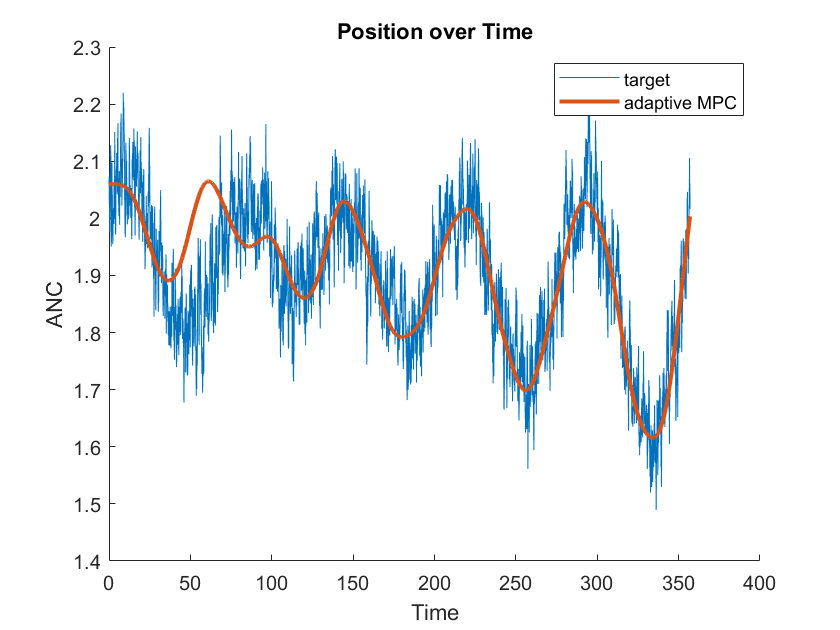

u_calc_full = zeros(size(u_nominal));
for k=1:N_days
    i = N_steps_per_day*(k-1);
    u_calc_full(i+1:i+N_steps_per_day,:) = u_calc(k)*(ones(N_steps_per_day,1));
end

y_neutrophils = reshape(y_calc(1,1,:),[1 N_steps+1]);
figure()
hold on
plot(time,rho)
plot(time, y_neutrophils, "LineWidth", 2)
title('Position over Time')
xlabel('Time')
ylabel('ANC')
legend('target','adaptive MPC')
hold off

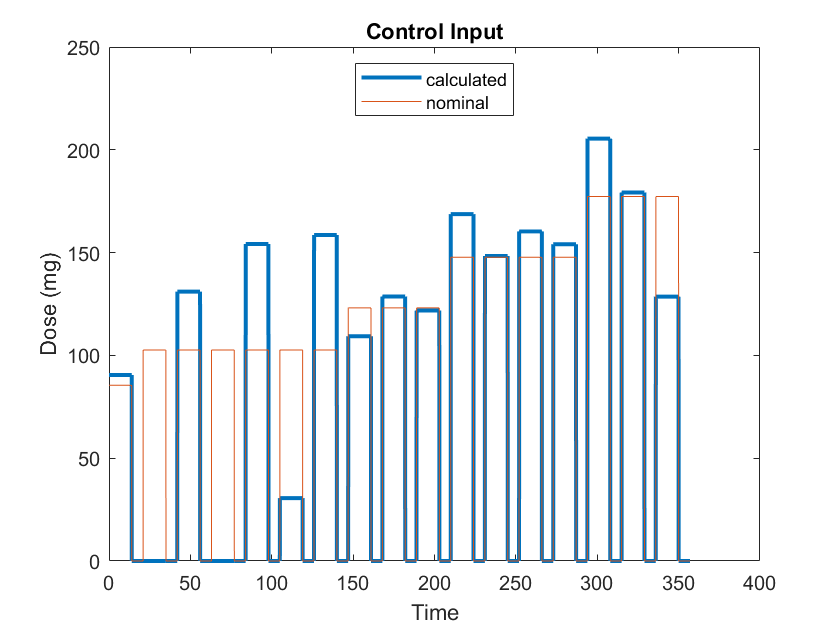


figure()
plot(time,u_calc_full, "LineWidth", 2)
hold on
plot(time,u_nominal)
title('Control Input')
xlabel('Time')
ylabel('Dose (mg)')
l = legend('calculated','nominal');
l.Location = "north";
hold off

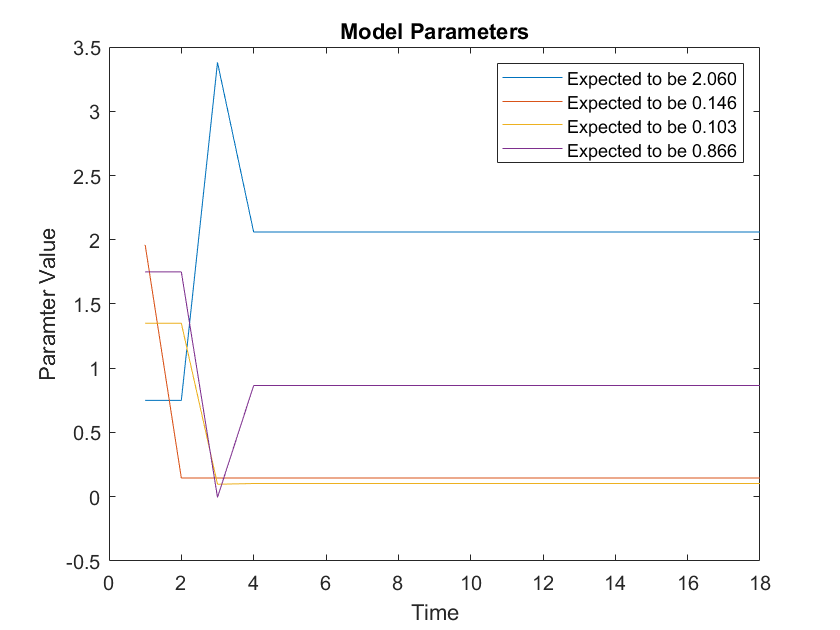


p1 = reshape(params_calc(1,1,:),[1 N_cyclestotal+1]);
p2 = reshape(params_calc(2,1,:),[1 N_cyclestotal+1]);
p3 = reshape(params_calc(3,1,:),[1 N_cyclestotal+1]);
p4 = reshape(params_calc(4,1,:),[1 N_cyclestotal+1]);
figure()
plot(p1)
hold on
plot(p2)
hold on
plot(p3)
hold on
plot(p4)
title('Model Parameters')
xlabel('Time')
ylabel('Paramter Value')
legend(...
    sprintf('Expected to be %0.3f', p_actual(1)), ...
    sprintf('Expected to be %0.3f', p_actual(2)), ...
    sprintf('Expected to be %0.3f', p_actual(3)), ...
    sprintf('Expected to be %0.3f', p_actual(4)) ...
)
hold off